# Offline Classification From Features

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This shell code expects that you have:

-  data with features already extracted in a variable called feature_table

- labels for the data in a variable called labels. 

The features should be in a table with the rows equal to the number of trials and the columns equal to the number of features. You can select a subset of features in the code below.

clear

Indicate if your test data is in a separate file or partitioned from the train data.

Make a list of files to load. If this has two things, the code will assume it is the train features followed by the test features. If it has one item, it will assume they are training featues and run a train-test split.  

If you want to use resubstitution, put the same training data twice (once as train, once as test).

% filesToLoad = {"training_table_stuff"}; % you'll need to change this name

filesToLoad = {"Finaltraining_table_stuff.mat","Finaltest_table_stuff.mat"}; %Do this for resubstitution

%filesToLoad = {"train_feature_table.mat", "test_feature_table.mat"}; 


#### Select which features you want. selected_features is the indices of these features. You can get fancy and use contains() if you want to pull them out by name.

% temporarily load the feature data to get selected features
load(filesToLoad{1})

Print out all the feature names

feature_table.Properties.VariableNames

ans = 1×20 cell array
    {'var_Ch1'}    {'var_Ch2'}    {'var_Ch3'}    {'var_Ch4'}    {'std_Ch1'}    {'std_Ch2'}    {'std_Ch3'}    {'std_Ch4'}    {'mad_Ch1'}    {'mad_Ch2'}    {'mad_Ch3'}    {'mad_Ch4'}    {'meanfreq_Ch1'}    {'meanfreq_Ch2'}    {'meanfreq_Ch3'}    {'meanfreq_Ch4'}    {'medfreq_Ch1'}    {'medfreq_Ch2'}    {'medfreq_Ch3'}    {'medfreq_Ch4'}


Select a subset of features (or all of them)

% selected_features = 1:size(feature_table,2); % This selects all features
selected_features = [
  % 1 2 3 4
  % 5 6 7 8
  9 10 11 12
  % 13 14 15 16
  17 18 19 20
   ]; %This selects the first two features listed above

selected_channels = [2 3 4]

selected_channels =      2     3     4


channel_mask = zeros(1,4)

channel_mask =      0     0     0     0


for i = 1:length(selected_channels)
    channel_mask(selected_channels(i)) = 1
end

channel_mask =      0     1     0     0


channel_mask =      0     1     1     0


channel_mask =      0     1     1     1


for j = 1:4
    selected_features(:,j) = selected_features(:,j) * channel_mask(j)
end

selected_features =      0    10    11    12
     0    18    19    20


selected_features =      0    10    11    12
     0    18    19    20


selected_features =      0    10    11    12
     0    18    19    20


selected_features =      0    10    11    12
     0    18    19    20


selected_features = nonzeros(selected_features)

selected_features =     10
    18
    11
    19
    12
    20







clearvars feature_table labels  % you just temporarily loaded these in to
%get the feature names, delete them so you don't get confused



## Load the feature data and put into X and y matrices

Look inside the function below to set things like train-test split.

[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);


## Build a classifier and do k-fold cross-validation

% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 335


  Properties, Methods


theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 334


  Properties, Methods


theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 334


  Properties, Methods


theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 334


  Properties, Methods


theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 335


  Properties, Methods


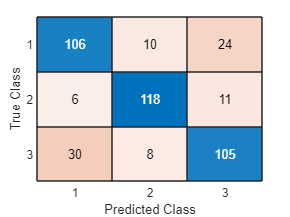

confusion =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


confusion_matrix =    106    10    24
     6   118    11
    30     8   105


f1_score = 0.7518

f1_score =     0.7518    0.8708


f1_score =     0.7518    0.8708    0.7420


validation_accuracy = 0.7871

validation_recall =     0.7571    0.8741    0.7343



% Calculate cross-validation metrics
[validation_accuracy, ~, validation_recall  ] = calculateMetrics(y_train, validation_predictions)

## Build a classifer on all of the training data

By making a createClassifier function, we can better ensure that the classifier we're using for the model and for cross-validation are the same. You can also make this into a function with other options (like which classifier to use or some paramter in the classifier that you want to vary).

% Create a classifier  
currentClassifier = createClassifier(X_train, y_train);

theClassifier =   ClassificationTree
           PredictorNames: {'mad_Ch2'  'medfreq_Ch2'  'mad_Ch3'  'medfreq_Ch3'  'mad_Ch4'  'medfreq_Ch4'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 418


  Properties, Methods


## Use classifier to predict on training data (resubstitution)

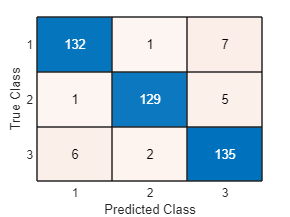

confusion =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


confusion_matrix =    132     1     7
     1   129     5
     6     2   135


f1_score = 0.9462

f1_score =     0.9462    0.9663


f1_score =     0.9462    0.9663    0.9310


train_accuracy = 0.9474

train_recall =     0.9429    0.9556    0.9441


y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy, ~, train_recall ] = calculateMetrics(y_train, y_train_predictions)

## Use classifier to predict on test data

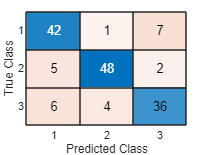

confusion =   ConfusionMatrixChart with properties:

    NormalizedValues: [3×3 double]
         ClassLabels: [3×1 double]

  Show all properties


confusion_matrix =     42     1     7
     5    48     2
     6     4    36


f1_score = 0.8155

f1_score =     0.8155    0.8889


f1_score =     0.8155    0.8889    0.7912


test_accuracy = 0.8344

test_recall =     0.8400    0.8727    0.7826


y_test_predictions = currentClassifier.predict(X_test);
[test_accuracy , ~, test_recall] = calculateMetrics(y_test, y_test_predictions)

# Helper functions

The code after this are functions that you can use and modify. By using functions to do more of the detailed work, we can better see the big picture above. And, we can better reuse the same code.

## Create X_train, y_train, X_test, and y_test. Configure train-test split here.

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)


True if you have separate test data to load (or just use all the train data again), false if you want to partition it from the data.

    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else 
        error("Wrong number of files to load.")
    end
    
    %

Load the training data. This is expecting your features to be in a table called feature_table. 

    load(filesToLoad{1})

#### If separate test data

    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:,selected_features);
        y_train = R1R2traingesturelist;
    
    
        % If you just want to use your train data again (resubstitution), just
        % get rid of the load part and repeat the step above.
    
        % Load the test data (here, it's the same file.. so fix this)
        load(filesToLoad{2});
    
        % Put the test data into X and y  
        % You might need to change variable names here
        X_test = feature_table(:,selected_features);
        y_test = R1R2testgesturelist;
    

#### If split the train / test data from one file

    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;
        try 
            % If it exists, Load a saved partition from last time (so you don't keep
            % shufflig which dat is your train and test)
            load("lastCVpartition.mat")
            disp("loading prior training-test partition")
            if cvtt.NumObservations ~= length(labels) || cvtt.TestSize/cvtt.NumObservations ~= holdout_proportion_test
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                
                cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            end
        catch
            cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            save("./lastCVpartition.mat","cvtt");
            disp('Making new training-test partiton')
        end
        
        % Train data
        X_train = feature_table(training(cvtt),selected_features);
        y_train = R1R2traingesturelist(training(cvtt));
    
        %Test datac
        X_test = feature_table(test(cvtt),selected_features);
        y_test = R1R2testgesturelist(test(cvtt));
    end
end


## Build a model based on data

There are various models that you can use here for 3 classes. You can add more details / parameters here.

function [theClassifier] = createClassifier(dataIn, labelsIn)
    
    % Linear discriminant analysis
    % theClassifier = fitcdiscr(dataIn,labelsIn);

    % Decision tree
    theClassifier = fitctree(dataIn,labelsIn)

    % fitcknn does k-nearest neighbors
    % theClassifier = fitcknn(dataIn,labelsIn,...
    %    "NumNeighbors",3);

end


## Calculate key metrics

You can put your other key metrics (such as F1 score) in here. You'll need to add more outputs to your function. 

function [accuracy, f1_score, recall ] = calculateMetrics(true_labels, predicted_labels)
    
    accuracy = sum(true_labels == predicted_labels) / length(true_labels);
    confusion = confusionchart(true_labels, predicted_labels)
    confusion_matrix = confusion.NormalizedValues
    num_classes = 3;
    for i = 1:num_classes
        true_positive = confusion_matrix(i, i);
        false_positive = sum(confusion_matrix(:, i)) - true_positive;
        false_negative = sum(confusion_matrix(i, :)) - true_positive;

        % Calculate precision
        precision(i) = true_positive / (true_positive + false_positive);

        % Calculate recall
        recall(i) = true_positive / (true_positive + false_negative);

        % Calculate F1 score
        f1_score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i))
    end
end
